# Simulate acoustic tunnel data in steps

Make a more accurate and faster simulation. 

Take advantage of two facts - 

One is that the chirps or pips have some distance between them. This means that for a large part of the simulation timespan, we dont need to simulate data, we should only concern ourselves by looking at what sections of the final timeshifted signal at the microphone points will have data. 

Two (related to one), is that the direction of the bat changes very little during the chirp, so we can basically treat it as one position. This leads to a more simple simulation strategy:

- find out when each chirp starts in the signal

- find out the position and direction of the bat during each of these chirps

- compute the amplitude of each source at each miceophone at each of these timesteps (and the delay)

- take the signal at each chirp section, compute the delay (where it would be in the reconstructed microphone signal) and do this for all the sources, then sum the contributions.

This means that we only compute data **for each chirp, rather than** **each timestep**, which VASTLY increases the speed of simulation!

#### Setup geometry and flight path

%import all geometry
%import all of the array geometry
clc
clear all
load("Sub Functions and Data\AcousticTunnelBasicGeometrySparse.mat")

%for these three things, there will eventually be complex functions to set
%them for each timestep to get some nice data, but for now keep it simple

%set the sampling rate for the signal
Fs = 5e5;

%number of seconds to simulate
numSec = 2;

%set the timesteps 
simTimeSteps = 0:(1/Fs):numSec;

%change the shirp signal to actual bat

%set the beam pattern characteristics
phiSpan = -2*pi:0.1:2*pi;
thetaSpan = -2*pi:0.1:2*pi;
beamPatternVars = struct("Amp",4,"Sigx",pi/8,"Sigy",pi/8,"Vo",0,"phiSpan",phiSpan,"thetaSpan",thetaSpan);

%position and rotation generated randomly
flightData = generateSimpleFlightPattern(arrayFullGeomData,simTimeSteps,0.5,0.25,1);
batPosOverTime = flightData.Locations;
batRotationOverTime = flightData.Directions;

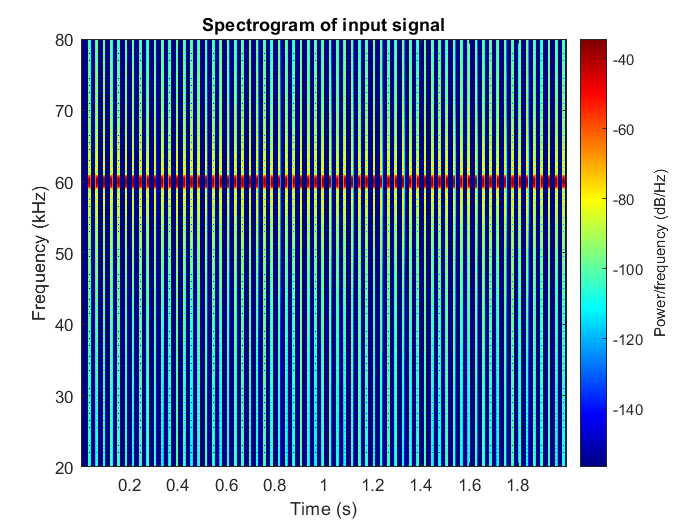

%finally, set the base output signal over time (make sure to double it)
%set a chirp length
chirpLen = 10e-3;

%set the chirp spacing
chirpSpacing = 20e-3;


%create the single chirp
singleChirpArray = 0:1/Fs:chirpLen;
singleChirp = sin(2*pi*60e3*singleChirpArray);

%here we can also create another chirp to be more like a bats chirp
halfChirpArray = 0:1/Fs:0.5*chirpLen;
firstHalfChirp = sin(2*pi*60e3*halfChirpArray);
secondHalfChirp = chirp(halfChirpArray,60e3,0.5*chirpLen,50e3,'quadratic',[],'convex');
%singleChirp = [firstHalfChirp,secondHalfChirp];
%singleChirp = singleChirp(2:end);

%create sine
singleSineFunc = sin(2*pi*(1/20e-3)*[0:1/Fs:chirpLen]);

%create the single chirp
singleChirp = singleChirp.*singleSineFunc;

%create the length of chirps
chirps = customChirp(simTimeSteps,singleChirp,chirpSpacing*Fs);

%set the output signal
outputSignalOverTime = chirps;

%compute the total number of chirps
totNumChirps = numSec/(chirpLen+chirpSpacing);

%plot the chirps over time
figure(1)
clf
spectrogram(outputSignalOverTime,1000,500,20*1e3:50:80*1e3,Fs,'yaxis');
title("Spectrogram of input signal")
colormap('jet')

%setup the geometry, we can preallocate the array for the geometry points
micPointsGeom = arrayFullGeomData.micPositions;

%setup the struct
geomData = struct("geometryData",[]);
geomData(1).geometryData = micPointsGeom;
geomData(2).geometryData = batPosOverTime(1,:);

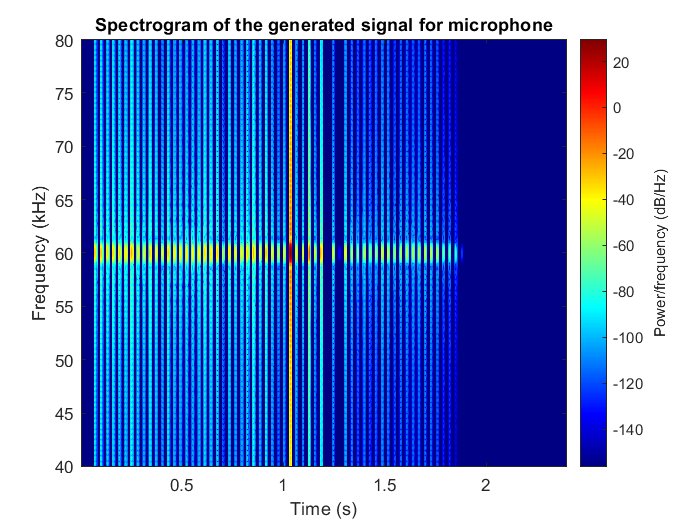

%create the full solution struct
fullSolutionStruct = struct("geomSolutions",[],"geometryData",[]);

%create the solution time arrays, which have one large time array for each
%data point in the solution
for g = 1:length(geomData)
    
    %set the data in the solution
    solData = zeros(size(geomData(g).geometryData,1),round(length(simTimeSteps)*1.2));
    

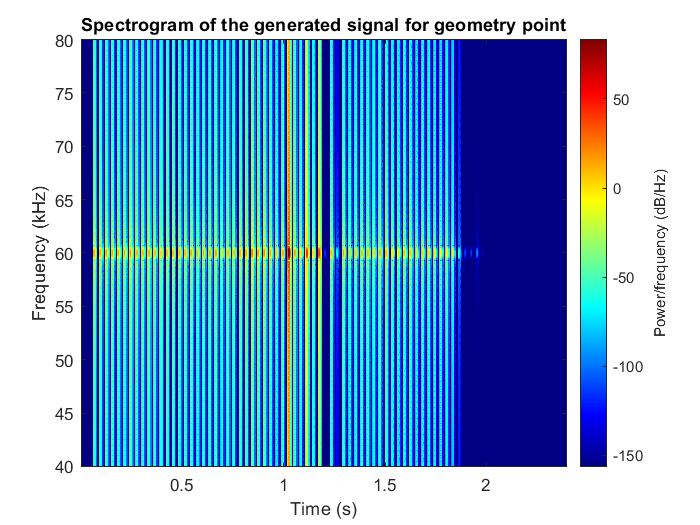

    %set the geometry solution
    fullSolutionStruct(g).geomSolutions = solData;
    
    %set the geometry for each 
    fullSolutionStruct(g).geometryData = geomData(g).geometryData;
    
end

%in this case, we change the second geometry point at each timestep, to a
%point which follows the bat position, initially just set this


%save the t values
tValues = [];

%for each timestep, compute the solution struct
for chirpStep = 1:totNumChirps
    
    %get the timestep, or the actual t value
    t = (chirpSpacing+chirpLen)*Fs*(chirpStep) + 1;
    tValues = [tValues;t];
    
    %get the chirp at that time
    chirpAtTime = outputSignalOverTime(t:t + (chirpLen)*Fs);
    
    %generate the source vars at this time
    beamPatternVars = struct("Amp",interpBeamData(t,1),"Sigx",interpBeamData(t,2),"Sigy",interpBeamData(t,3),"Vo",0,"phiSpan",phiSpan,"thetaSpan",thetaSpan);
    
    %compute the source direction from the beam pattern estimation
    sourceDirec = [sin(interpBeamData(t,3))*cos(interpBeamData(t,4)),sin(interpBeamData(t,3))*sin(interpBeamData(t,4)),cos(interpBeamData(t,3))];
    sourceDirec = sourceDirec/norm(sourceDirec);
    sourceVars = struct("Location",batPosOverTime(t,:),"Direction",sourceDirec);
    %sourceVars = struct("Location",batPosOverTime(t,:),"Direction",batRotationOverTime(t,:));
    
    %compute the solution    
    
    %generate the reflection location and directions for the timestep   
    reflectionSourcesStruct = struct("sourceVectors",[],"sourcePoints",[]);
    reflectionSourcesStruct = createESMReflectionSources(arrayFullGeomData,sourceVars);
    reflectionSourcesStruct.sourceVectors = [reflectionSourcesStruct.sourceVectors; sourceVars.Direction];
    reflectionSourcesStruct.sourcePoints = [reflectionSourcesStruct.sourcePoints; sourceVars.Location];

    %for each geometry
    for g = 1:length(geomData)
        
        %get the geometry
        evalPoints = geomData(g).geometryData;
        
        %in this case, for the second geometry, we can change the position
        %over time, also store this in the geometry data
        if g == 2
            evalPoints = batPosOverTime(t,:) + [0 0.1 0];
            
            fullSolutionStruct(2).geometryData = [fullSolutionStruct(2).geometryData;evalPoints];
        end
        
        %for each source
        for src = 1:size(reflectionSourcesStruct.sourcePoints,1)
            
            %get the bat orientation and direction 
            batOrientation = reflectionSourcesStruct.sourceVectors(src,:);
            sourcePos = reflectionSourcesStruct.sourcePoints(src,:);
            singleSourceVars = struct("Location",sourcePos,"Direction",batOrientation);
            
            %convert the point from cartesian to spherical
            %ALSO FIX THIS INTERPOLATION
            [th,elevation,r] = cart2sph((evalPoints(:,3) - sourcePos(3)),(evalPoints(:,2)  - sourcePos(2)),(evalPoints(:,1) - sourcePos(1)));
            
            %TODO: Modify code for imperfect reflection here (energy loss)
            %for all except the last rouce, which is the initial source

            %generate the beam pattern here, or take the vars from
            %pre-generated data
            [beamPatternSph, beamPatternLin] = generateBeamPatternBasic(singleSourceVars,beamPatternVars);
            
            %get the amplitude at that point based on the source
            %ampAtPoints = interp2(beamPatternVars.thetaSpan,beamPatternVars.phiSpan,beamPatternLin.amplitude,th,ro);
            ampAtPoints = interp2(beamPatternSph.theta,beamPatternSph.phi,beamPatternSph.amplitude,th,elevation);
            ampAtPoints(isnan(ampAtPoints)) = 0;
            
            %add the contribution from the 1/r squared term
            r(r == 0) = 0.0001;
            ampAtPoints = ampAtPoints.*(1./(r.^2));
            
            %calculate the sampling delay
            samplingDelays = r./343;
            
            %calculate the signal delay
            sigDelays = round(samplingDelays*Fs);
            
            %if the signal delay is 0, set it to 1
            sigDelays(sigDelays == 0) = 1;
            sigDelays(sigDelays > length(outputSignalOverTime)) = 1;
            
            %for each of the geom points
            for point = 1:length(ampAtPoints)
                
                %get the single time sampling delay
                singleSampDelay = sigDelays(point);
                
                %set the single time amplitude modifier
                ampMultiplier = ampAtPoints(point);
                
                %at the correct location in each point's solution time array 
                %add the portion of the input (after amplitude shifting)
                fullSolutionStruct(g).geomSolutions(point,(t+singleSampDelay):(t+singleSampDelay)+chirpLen*Fs) = ...
                    fullSolutionStruct(g).geomSolutions(point,(t+singleSampDelay):(t+singleSampDelay)+chirpLen*Fs) + chirpAtTime*ampMultiplier;
                
            end %end geometry point for
            
        end %end source for   
        
    end %end geometry for
    
    %display (occasionally)
    %disp("finished simulating: " + string(t) + " timesteps.")
end

%plot the spectrogram of a data point quickly to see if it works
singlePointData = fullSolutionStruct(1).geomSolutions(1,:);

%plot the spectrogram data
%plot a spectrogram of the data
figure(1)
clf
spectrogram(singlePointData,1000,500,40*1e3:100:80*1e3,Fs,'yaxis');
title("Spectrogram of the generated signal for microphone")
colormap('jet')
%get the geometry point data
geomPointData = fullSolutionStruct(2).geomSolutions(1,:);

%plot the spectrogram data
%plot a spectrogram of the data
figure(2)
clf
spectrogram(geomPointData,2000,500,40*1e3:100:80*1e3,Fs,'yaxis');
title("Spectrogram of the generated signal for geometry point")
colormap('jet')

%save all the data here
fullInputStruct = struct("signal",outputSignalOverTime,"beamPattern",beamPatternVars,"flightData",flightData,"timeSteps",simTimeSteps,"geometry",geomData,"chirpLen",chirpLen,...
    "chirpSpacing",chirpSpacing,"Fs",Fs,"tValues",tValues);
save("reconstructedSolution1.mat","fullSolutionStruct","fullInputStruct","interpBeamData",'-v7.3');
